## Лаба 3. Вынужденное движение и показатели качества

## Задание 1. Вынужденное движение

Параметры для запуска симуляции

simTimeStart = 0;
simTimeEnd = 10;
step = 0.02;
data.time=(simTimeStart:0.02:simTimeEnd)';
modelName = 'task1'; 

Эксперимент 1-й. 

lambda1 = -0.6 + 4j; lambda2 = -0.6 - 4j; c1 = 3/20; c2 = 1;
a0 = lambda1*lambda2

a0 = 16.3600

a1 = -(lambda1 + lambda2)

a1 = 1.2000

input1

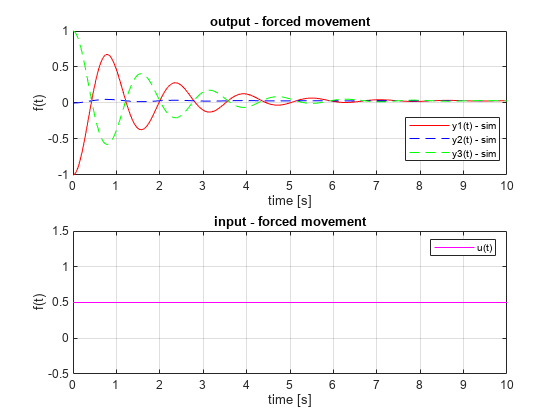

input = 0.5 * ones(1, length(data.time))';
data.signals(1).values=input;
data.signals(1).dimensions=1;

load_system(modelName);

y0 = -1; y1 = 0; % 1
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 0; y1 = 0; % 2
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 1; y1 = 0; % 3
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; 
y_out2 = out2.simout.Data; 
y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'b--');
hold on;
plot(time, y_out3, 'g--');
title('output - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y1(t) - sim', 'y2(t) - sim', 'y3(t) - sim', 'Location', 'Best');

subplot(2,1,2);
plot(time, input, 'magenta'); 
title('input - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp11')

input2

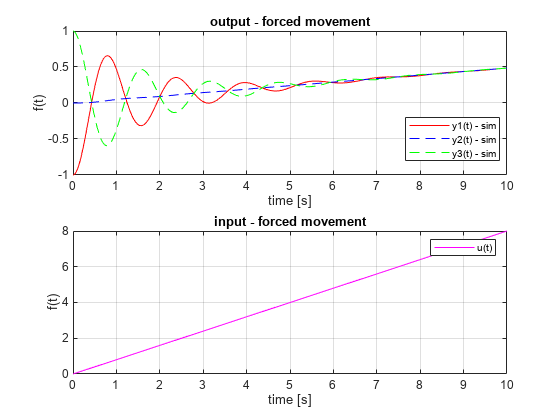

input = 0.8 * data.time;
data.signals(1).values=input;
data.signals(1).dimensions=1;

load_system(modelName);

y0 = -1; y1 = 0; % 1
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 0; y1 = 0; % 2
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 1; y1 = 0; % 3
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; 
y_out2 = out2.simout.Data; 
y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'b--');
hold on;
plot(time, y_out3, 'g--');
title('output - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y1(t) - sim', 'y2(t) - sim', 'y3(t) - sim', 'Location', 'Best');

subplot(2,1,2);
plot(time, input, 'magenta'); 
title('input - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp12')

input3

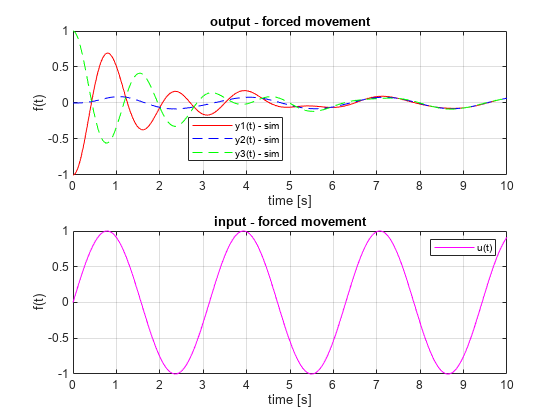

input = sin(data.time*2);
data.signals(1).values=input;
data.signals(1).dimensions=1;

load_system(modelName);

y0 = -1; y1 = 0; % 1
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 0; y1 = 0; % 2
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 1; y1 = 0; % 3
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; 
y_out2 = out2.simout.Data; 
y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'b--');
hold on;
plot(time, y_out3, 'g--');
title('output - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y1(t) - sim', 'y2(t) - sim', 'y3(t) - sim', 'Location', 'Best');

subplot(2,1,2);
plot(time, input, 'magenta'); 
title('input - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp13')

Эксперимент 2-й

lambda1 = 4j; lambda2 = -4j; c1 = 0; c2 = 1;
a0 = lambda1*lambda2

a0 = 16

a1 = -(lambda1 + lambda2)

a1 = 0

input1

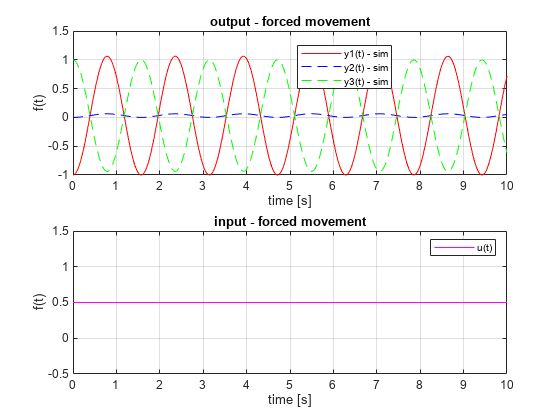

input = 0.5 * ones(1, length(data.time))';
data.signals(1).values=input;
data.signals(1).dimensions=1;

load_system(modelName);

y0 = -1; y1 = 0; % 1
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 0; y1 = 0; % 2
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 1; y1 = 0; % 3
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; 
y_out2 = out2.simout.Data; 
y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'b--');
hold on;
plot(time, y_out3, 'g--');
title('output - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y1(t) - sim', 'y2(t) - sim', 'y3(t) - sim', 'Location', 'Best');

subplot(2,1,2);
plot(time, input, 'magenta'); 
title('input - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp21')

input2

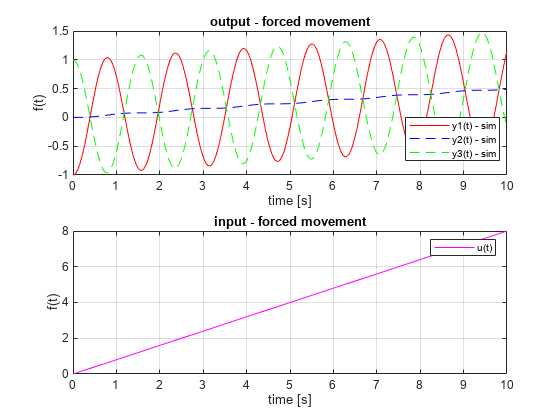

input = 0.8 * data.time;
data.signals(1).values=input;
data.signals(1).dimensions=1;

load_system(modelName);

y0 = -1; y1 = 0; % 1
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 0; y1 = 0; % 2
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 1; y1 = 0; % 3
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; 
y_out2 = out2.simout.Data; 
y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'b--');
hold on;
plot(time, y_out3, 'g--');
title('output - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y1(t) - sim', 'y2(t) - sim', 'y3(t) - sim', 'Location', 'Best');

subplot(2,1,2);
plot(time, input, 'magenta'); 
title('input - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp22')

input3

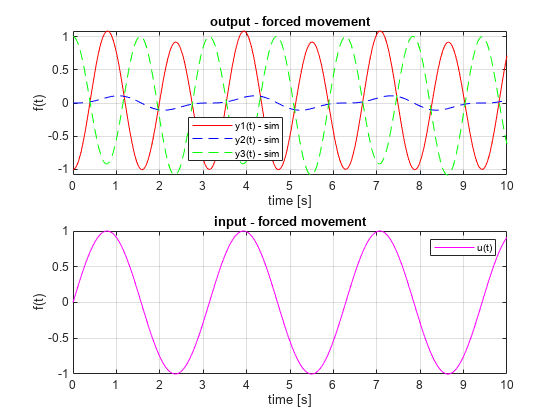

input = sin(data.time*2);
data.signals(1).values=input;
data.signals(1).dimensions=1;

load_system(modelName);

y0 = -1; y1 = 0; % 1
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 0; y1 = 0; % 2
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 1; y1 = 0; % 3
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; 
y_out2 = out2.simout.Data; 
y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'b--');
hold on;
plot(time, y_out3, 'g--');
title('output - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y1(t) - sim', 'y2(t) - sim', 'y3(t) - sim', 'Location', 'Best');

subplot(2,1,2);
plot(time, input, 'magenta'); 
title('input - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp23')

Эксперимент 3-й

lambda1 = 0.6 + 4j; lambda2 = 0.6 - 4j; c1 = -3/400; c2 = 0.05;
a0 = lambda1*lambda2

a0 = 16.3600

a1 = -(lambda1 + lambda2)

a1 = -1.2000

input1

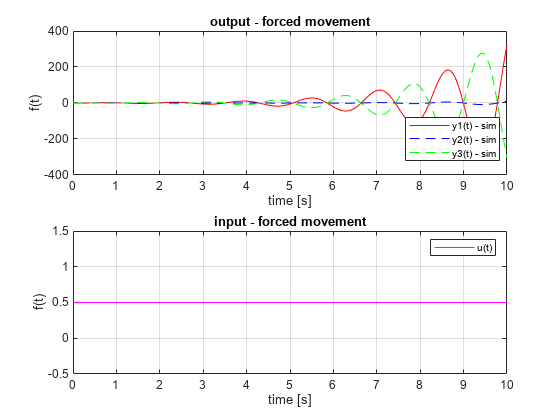

input = 0.5 * ones(1, length(data.time))';
data.signals(1).values=input;
data.signals(1).dimensions=1;

load_system(modelName);
y0 = -1; y1 = 0; % 1
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 0; y1 = 0; % 2
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 1; y1 = 0; % 3
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; 
y_out2 = out2.simout.Data; 
y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'b--');
hold on;
plot(time, y_out3, 'g--');
title('output - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y1(t) - sim', 'y2(t) - sim', 'y3(t) - sim', 'Location', 'Best');

subplot(2,1,2);
plot(time, input, 'magenta'); 
title('input - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp31')

input2

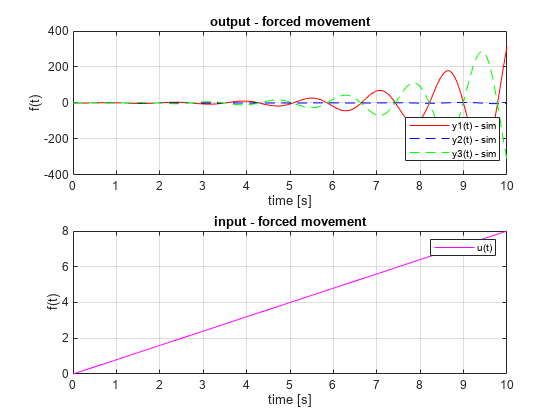

input = 0.8 * data.time;
data.signals(1).values=input;
data.signals(1).dimensions=1;

load_system(modelName);

y0 = -1; y1 = 0; % 1
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 0; y1 = 0; % 2
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 1; y1 = 0; % 3
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; 
y_out2 = out2.simout.Data; 
y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'b--');
hold on;
plot(time, y_out3, 'g--');
title('output - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y1(t) - sim', 'y2(t) - sim', 'y3(t) - sim', 'Location', 'Best');

subplot(2,1,2);
plot(time, input, 'magenta'); 
title('input - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp32')

input3

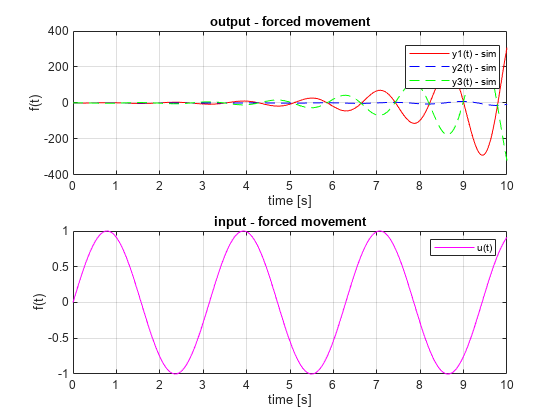

input = sin(data.time*2);
data.signals(1).values=input;
data.signals(1).dimensions=1;

load_system(modelName);

y0 = -1; y1 = 0; % 1
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 0; y1 = 0; % 2
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
y0 = 1; y1 = 0; % 3
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out1.simout.Time;                
y_out1 = out1.simout.Data; 
y_out2 = out2.simout.Data; 
y_out3 = out3.simout.Data; 

figure;
subplot(2,1,1);
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'b--');
hold on;
plot(time, y_out3, 'g--');
title('output - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y1(t) - sim', 'y2(t) - sim', 'y3(t) - sim', 'Location', 'Best');

subplot(2,1,2);
plot(time, input, 'magenta'); 
title('input - forced movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp33')

**Функция, чтобы сохранить файл в папку**

function save_file(name)
    path = 'D:\Math\control_theory\linear_systems_labs\lab3\latex3\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end